## Data Evaluation

data_path = 'C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\'

data_path = 'C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\'

save_path= "C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\figures";

% Dominant frequencies in each experiment
% Organized to where experiment_5(i) = dominant frequency of subject i.
[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "F8");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "F8");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "F8");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat


### Now that we have data gathered, we can pretty much do whatever we want.

One of the things we should consider is to obtain a *single* dominant frequency for each experiment. One metric we can use to obtain this is to consider the relative amplitudes of each peak.

We can use a 3d array here.

dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

### Removing messed up data (data segmented incorrectly)

Removing data from subject 5, experiment 5, and subject 3, experiment 6 and 7.

Also cutting out s07, s16, s18, s20

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Boxplots

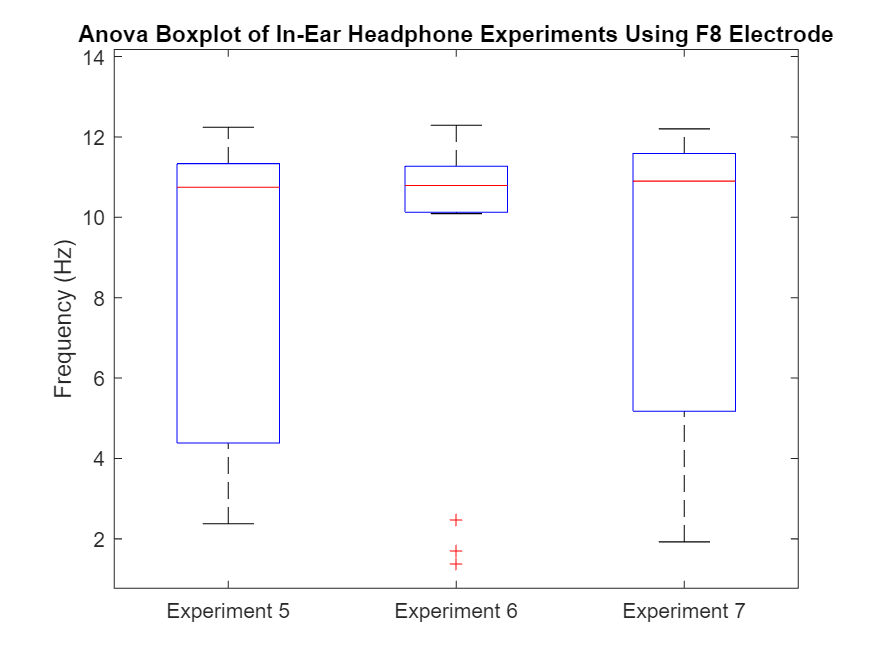

figure;
boxplot(dominant_freqs_trimmed);
F8_freqs = dominant_freqs_trimmed;
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Anova Boxplot of In-Ear Headphone Experiments Using F8 Electrode")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot_f8.png");
saveas(gcf, fig_path);

p-values, peforming t-test between datasets

% for i=1:size(dominant_freqs, 2)
%     freqs = dominant_freqs(:, i);
%     f = figure;
% end
% for i=1:size(dominant_freqs_trimmed, 2)
%     freqs = dominant_freqs_trimmed(:, i);
%     f = figure;
%     for j=1:size(dominant_freqs_trimmed, 2)
%         if (i ~= j)
%             comp_freqs = dominant_freqs_trimmed(:, j);
%             [~, p] = ttest(freqs, comp_freqs);
%             disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
%             disp(num2str(p));
%         end
%     end
% end

anova regression

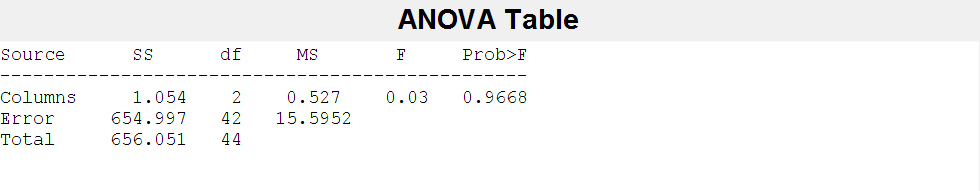

figure;
p = anova1(dominant_freqs_trimmed);

disp(strcat("p-value across all three experiments: ", num2str(p)));

p-value across all three experiments: 0.9668


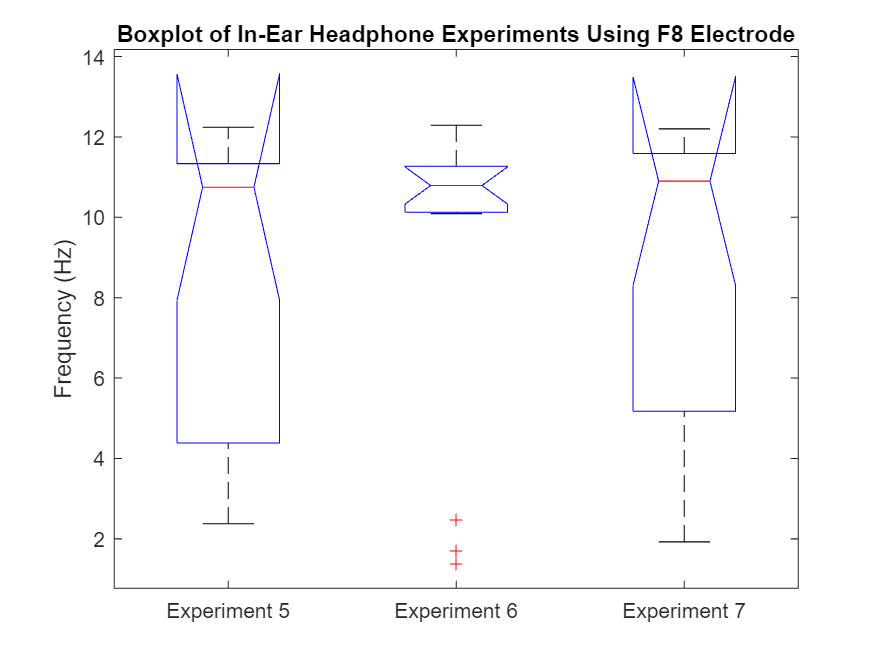

xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of In-Ear Headphone Experiments Using F8 Electrode")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "anova1_f8.png");
saveas(gcf, fig_path);

### Same Experiment With Different Electrodes

With T7

[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "T7");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "T7");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "T7");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat



dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Analysis

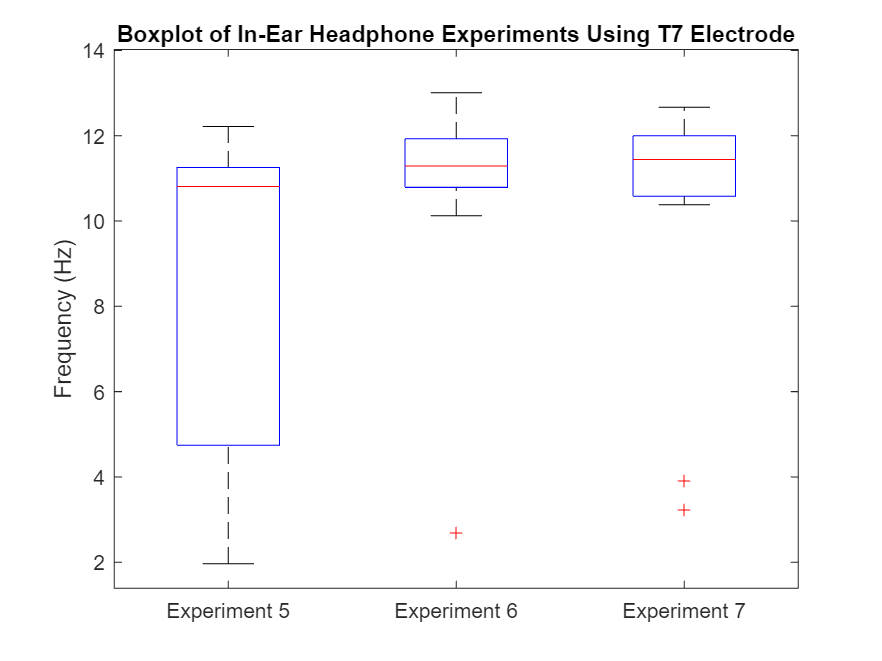

figure;
boxplot(dominant_freqs_trimmed);
T7_freqs = dominant_freqs_trimmed;
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of In-Ear Headphone Experiments Using T7 Electrode")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot_t7.png");
saveas(gcf, fig_path);

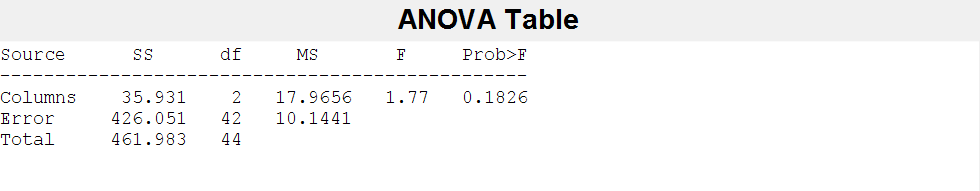

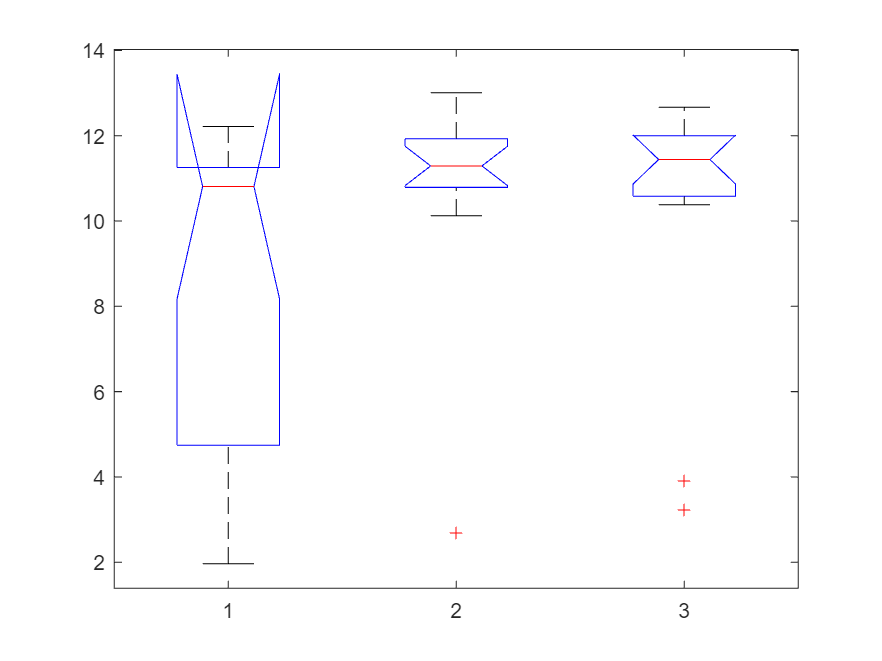


% for i=1:size(dominant_freqs_trimmed, 2)
%     freqs = dominant_freqs_trimmed(:, i);
%     f = figure;
%     for j=1:size(dominant_freqs_trimmed, 2)
%         if (i ~= j)
%             comp_freqs = dominant_freqs_trimmed(:, j);
%             [~, p] = ttest(freqs, comp_freqs);
%             disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
%             disp(num2str(p));
%         end
%     end
% end

p = anova1(dominant_freqs_trimmed);

disp(strcat("p-value across all three experiments: ", num2str(p)));

p-value across all three experiments: 0.18263


With midline

[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "Cz");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "Cz");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "Cz");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat



dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Analysis

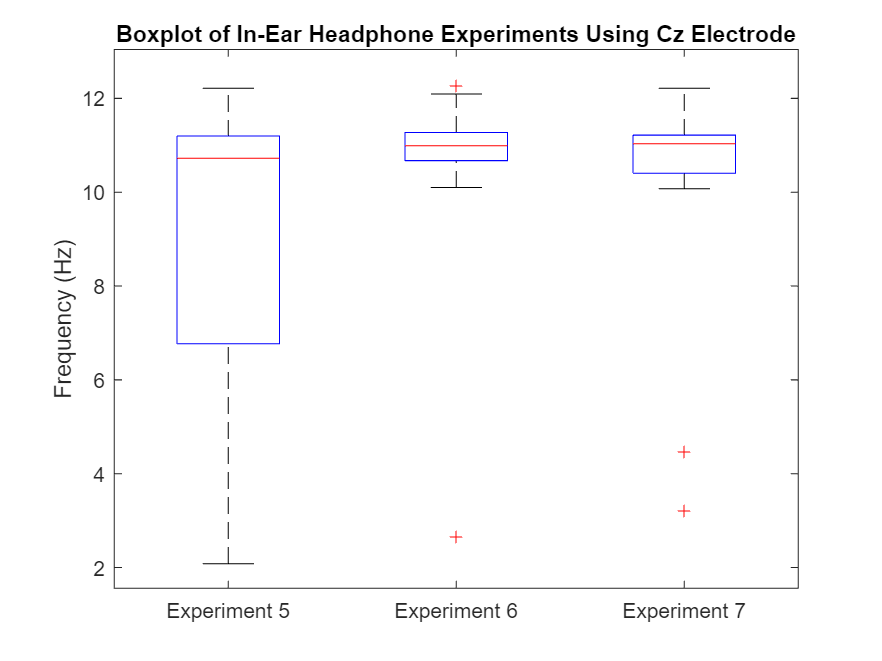

figure;
boxplot(dominant_freqs_trimmed);
Cz_freqs = dominant_freqs_trimmed;
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of In-Ear Headphone Experiments Using Cz Electrode")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot_cz.png");
saveas(gcf, fig_path);

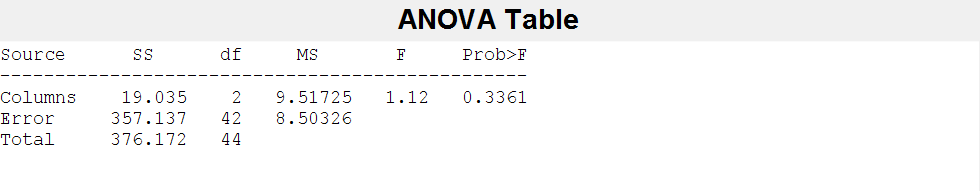

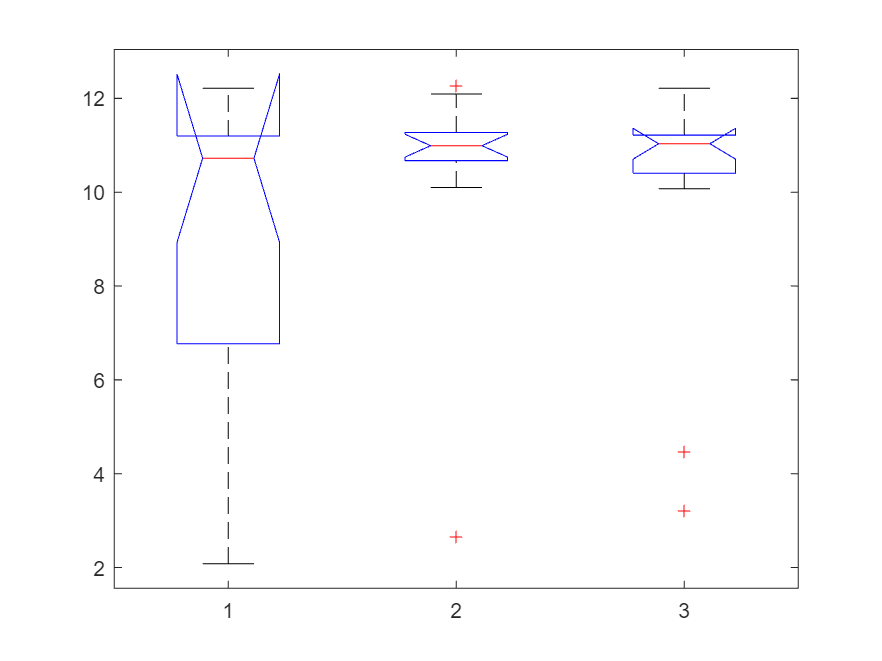


% for i=1:size(dominant_freqs_trimmed, 2)
%     freqs = dominant_freqs_trimmed(:, i);
%     f = figure;
%     for j=1:size(dominant_freqs_trimmed, 2)
%         if (i ~= j)
%             comp_freqs = dominant_freqs_trimmed(:, j);
%             [~, p] = ttest(freqs, comp_freqs);
%             disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
%             disp(num2str(p));
%         end
%     end
% end

p = anova1(dominant_freqs_trimmed);

disp(strcat("p-value across all three experiments: ", num2str(p)));

p-value across all three experiments: 0.33607


With parietal

[exp_5_freqs, exp_5_amps] = data_eval(data_path, "05", "P4");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s05_ex05.mat


[exp_6_freqs, exp_6_amps] = data_eval(data_path, "06", "P4");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex06.mat


[exp_7_freqs, exp_7_amps] = data_eval(data_path, "07", "P4");

Data not segmented properly: C:\Users\dnxjc\OneDrive\Desktop\CURR\bme 1\FINAL PROJECT\data\Filtered_Data_mat\s03_ex07.mat



dominant_freqs = zeros(20,1,3);
dominant_freqs(:, 1, 1) = max(exp_5_freqs .* (max(exp_5_amps, [], 2) == exp_5_amps), [], 2);
dominant_freqs(:, 1, 2) = max(exp_6_freqs .* (max(exp_6_amps, [], 2) == exp_6_amps), [], 2);
dominant_freqs(:, 1, 3) = max(exp_7_freqs .* (max(exp_7_amps, [], 2) == exp_7_amps), [], 2);

dominant_freqs_trimmed = cat(2, dominant_freqs(cat(2, 1:4, 6, 8:15, 17, 19), 1, 1), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 2), ...
    dominant_freqs(cat(2, 1:2, 4:6, 8:15, 17, 19), 1, 3));

Analysis

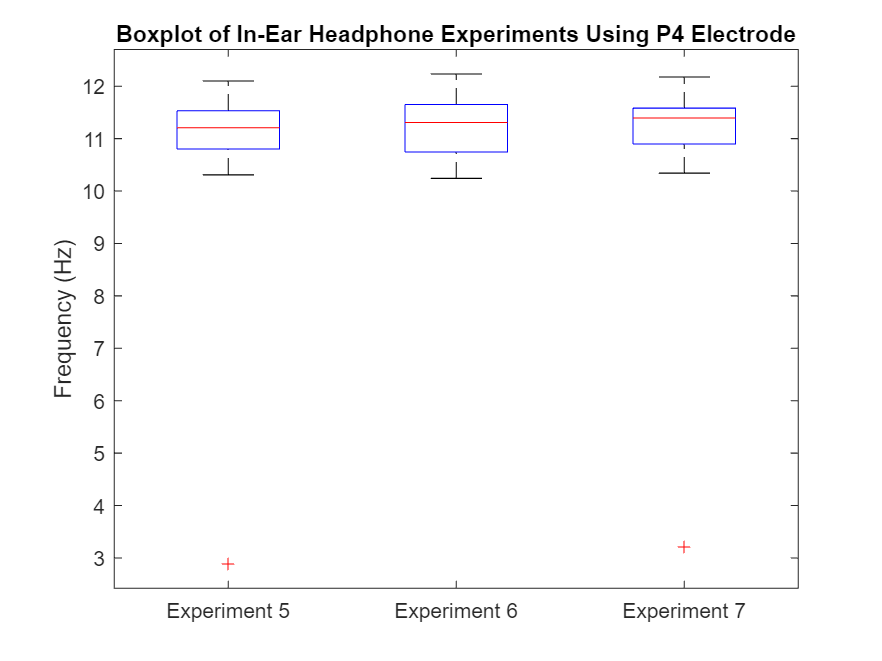

figure;
boxplot(dominant_freqs_trimmed);
P4_freqs = dominant_freqs_trimmed;
xticklabels({'Experiment 5','Experiment 6','Experiment 7'});
title("Boxplot of In-Ear Headphone Experiments Using P4 Electrode")
ylabel("Frequency (Hz)");
fig_path = fullfile(save_path, "boxplot_p4.png");
saveas(gcf, fig_path);

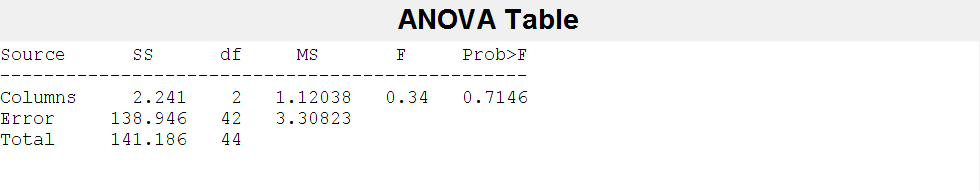

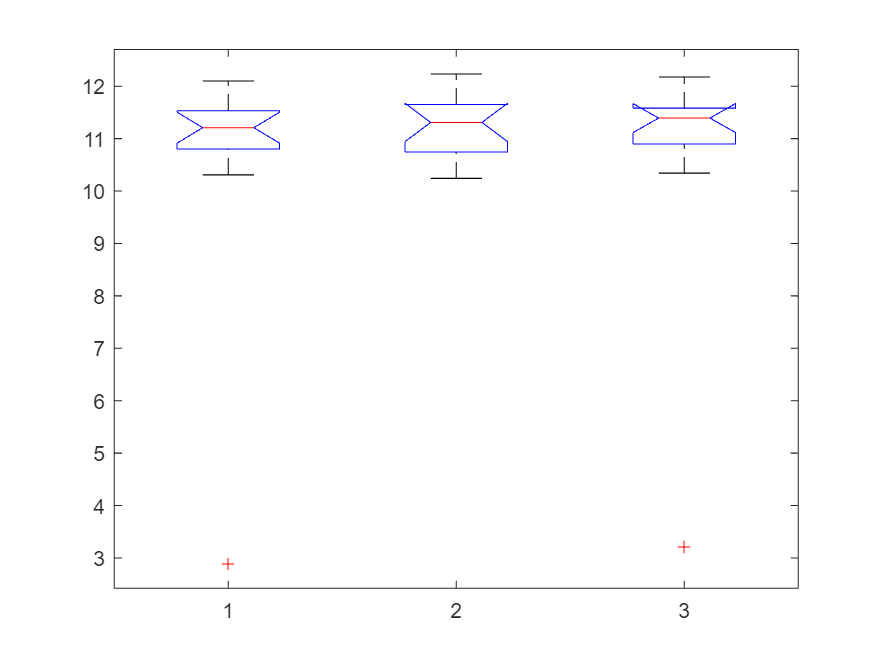


% for i=1:size(dominant_freqs_trimmed, 2)
%     freqs = dominant_freqs_trimmed(:, i);
%     f = figure;
%     for j=1:size(dominant_freqs_trimmed, 2)
%         if (i ~= j)
%             comp_freqs = dominant_freqs_trimmed(:, j);
%             [~, p] = ttest(freqs, comp_freqs);
%             disp(strcat("Comparing ", num2str(i), " and ", num2str(j)));
%             disp(num2str(p));
%         end
%     end
% end

p = anova1(dominant_freqs_trimmed);

disp(strcat("p-value across all three experiments: ", num2str(p)));

p-value across all three experiments: 0.71465


Creating combined figure for easier use.

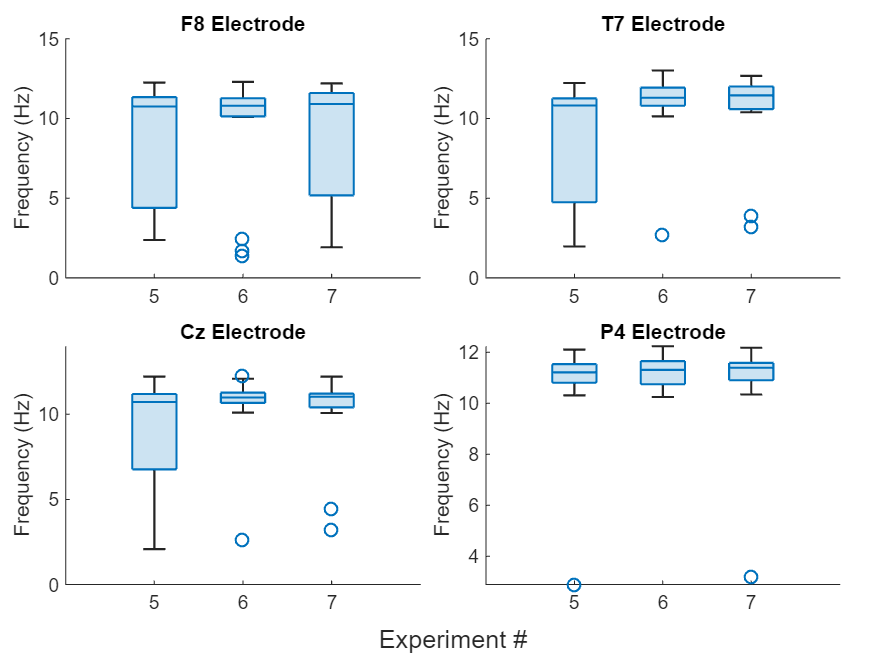

% sheet_figure = figure;
figure;
% axis image;

sheet = tiledlayout('flow','TileSpacing','compact','Padding','compact');

% F8
nexttile;
boxchart(F8_freqs);

ylabel("Frequency (Hz)");
title("F8 Electrode")
xticklabels({'5','6','7'});
% set(gca,'LooseInset',get(gca,'TightInset'));

% T7
nexttile;
boxchart(T7_freqs);

ylabel("Frequency (Hz)");
title("T7 Electrode")
xticklabels({'5','6','7'});
% set(gca,'LooseInset',get(gca,'TightInset'));

% Cz
nexttile;
boxchart(Cz_freqs);

ylabel("Frequency (Hz)");
title("Cz Electrode")
xticklabels({'5','6','7'});
ylim([0 14])
% set(gca,'LooseInset',get(gca,'TightInset'));

% P4
nexttile;
boxchart(P4_freqs);

ylabel("Frequency (Hz)");
title("P4 Electrode")
xticklabels({'5','6','7'});
% set(gca,'LooseInset',get(gca,'TightInset'));


% title(sheet, "Boxplots of In-Ear Headphone Esxperiments Using Different Electrodes");
xlabel(sheet, "Experiment #")
fig_path = fullfile(save_path, "boxplot_all.png");
saveas(gcf, fig_path);